**2.6 Undoing Perspective Distortion of Planar Surface**

The goal in this part of the experiment is to take an original slanted view of a book, and compute the projective transformation to warp the image to a frontal view. The final warped image should have the scale 1 pixel (image) = 1 mm (book dimension).

The following paragraph provides the basic knowledge on 2D planar projective transformation. A 2D planar projective transform is expressed via a 3x3 matrix:


$$\left\lbrack \begin{array}{c}
kx_{\mathrm{im}} \\
ky_{\mathrm{im}} \\
k
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
m_{11}  & m_{12}  & m_{13} \\
m_{21}  & m_{22}  & m_{23} \\
m_{31}  & m_{32}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X_w \\
Y_w \\
1
\end{array}\right\rbrack$$


where $X_w$ and $Y_w$ are the coordinates of a point in the input image, while $x_{\mathrm{im}}$ and $y_{\mathrm{im}}$ are the coordinates of the transformed point in the output image. This can be alternatively expressed in algebraic form:

$x_{\mathrm{im}} =\frac{m_{11} X_w +m_{12} Y_w +m_{13} }{m_{31} X_w +m_{32} Y_w +1}$, $y_{\mathrm{im}}$ = $\frac{m_{21} X_w +m_{22} Y_w +m_{23} }{m_{31} X_w +m_{32} Y_w +1}$

Since there are only 8 degrees of freedom in the projective matrix (i.e., 8 unknowns), we can compute this matrix if we know the correspondence between 4 or more points in the input image and the output image. Using the correspondences and the above equations, the following matrix equation may be set up

$\left\lbrack \begin{array}{cccccccc}
X_w^1  & Y_w^1  & 1 & 0 & 0 & 0 & -x_{\textrm{im}}^1 X_w^1  & -x_{\textrm{im}}^1 Y_w^1 \\
0 & 0 & 0 & X_w^1  & Y_w^1  & 1 & -y_{\textrm{im}}^1 X_w^1  & -y_{\textrm{im}}^1 Y_w^1 \\
X_w^2  & Y_w^2  & 1 & 0 & 0 & 0 & -x_{\textrm{im}}^2 X_w^2  & -x_{\textrm{im}}^2 Y_w^2 \\
0 & 0 & 0 & X_w^2  & Y_w^2  & 1 & -y_{\textrm{im}}^2 X_w^2  & -y_{\textrm{im}}^2 Y_w^2 \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
\ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp  & \ldotp \\
X_w^n  & Y_w^n  & 1 & 0 & 0 & 0 & -x_{\textrm{im}}^n X_w^n  & -x_{\textrm{im}}^n Y_w^n \\
0 & 0 & 0 & X_w^n  & Y_w^n  & 1 & -y_{\textrm{im}}^n X_w^n  & -y_{\textrm{im}}^n Y_w^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m_{11} \\
m_{12} \\
m_{13} \\
m_{21} \\
m_{22} \\
m_{23} \\
m_{31} \\
m_{32} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_{\textrm{im}}^1 \\
y_{\textrm{im}}^1 \\
x_{\textrm{im}}^2 \\
y_{\textrm{im}}^2 \\
\ldotp \\
\ldotp \\
x_{\textrm{im}}^n \\
y_{\textrm{im}}^n 
\end{array}\right\rbrack$.(*)

We can write the above equation in the form of Au = v, where A and v are the 8x8 matrix and 8x1 vector respectively, containing corner data, while u is the 8x1 vector of projective transformation parameters to be computed.

This equation allows the computation of an unknown projective transformation through simple matrix inversion (for 4 correspondences) or pseudo-inversion (for >4 correspondences).

Now please start to go through the following steps.

a. Download `book.jpg’ from the edveNTUre website as a matrix P and display the image. The image is a slanted view of a book of A4 dimensions, which is 210 mm x 297 mm.

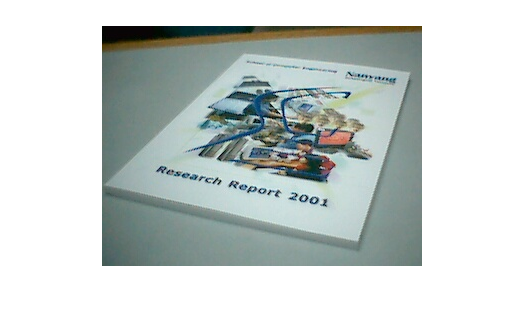

bookImage = imread('images/book.jpg');
imshow(bookImage);

whos bookImage;

  Name             Size                Bytes  Class    Attributes

  bookImage      240x320x3            230400  uint8              



b. The **ginput** function allows you to interactively click on points in the figure to obtain the image coordinates. Use this to find out the location of 4 corners of the book, remembering the order in which you measure the corners.

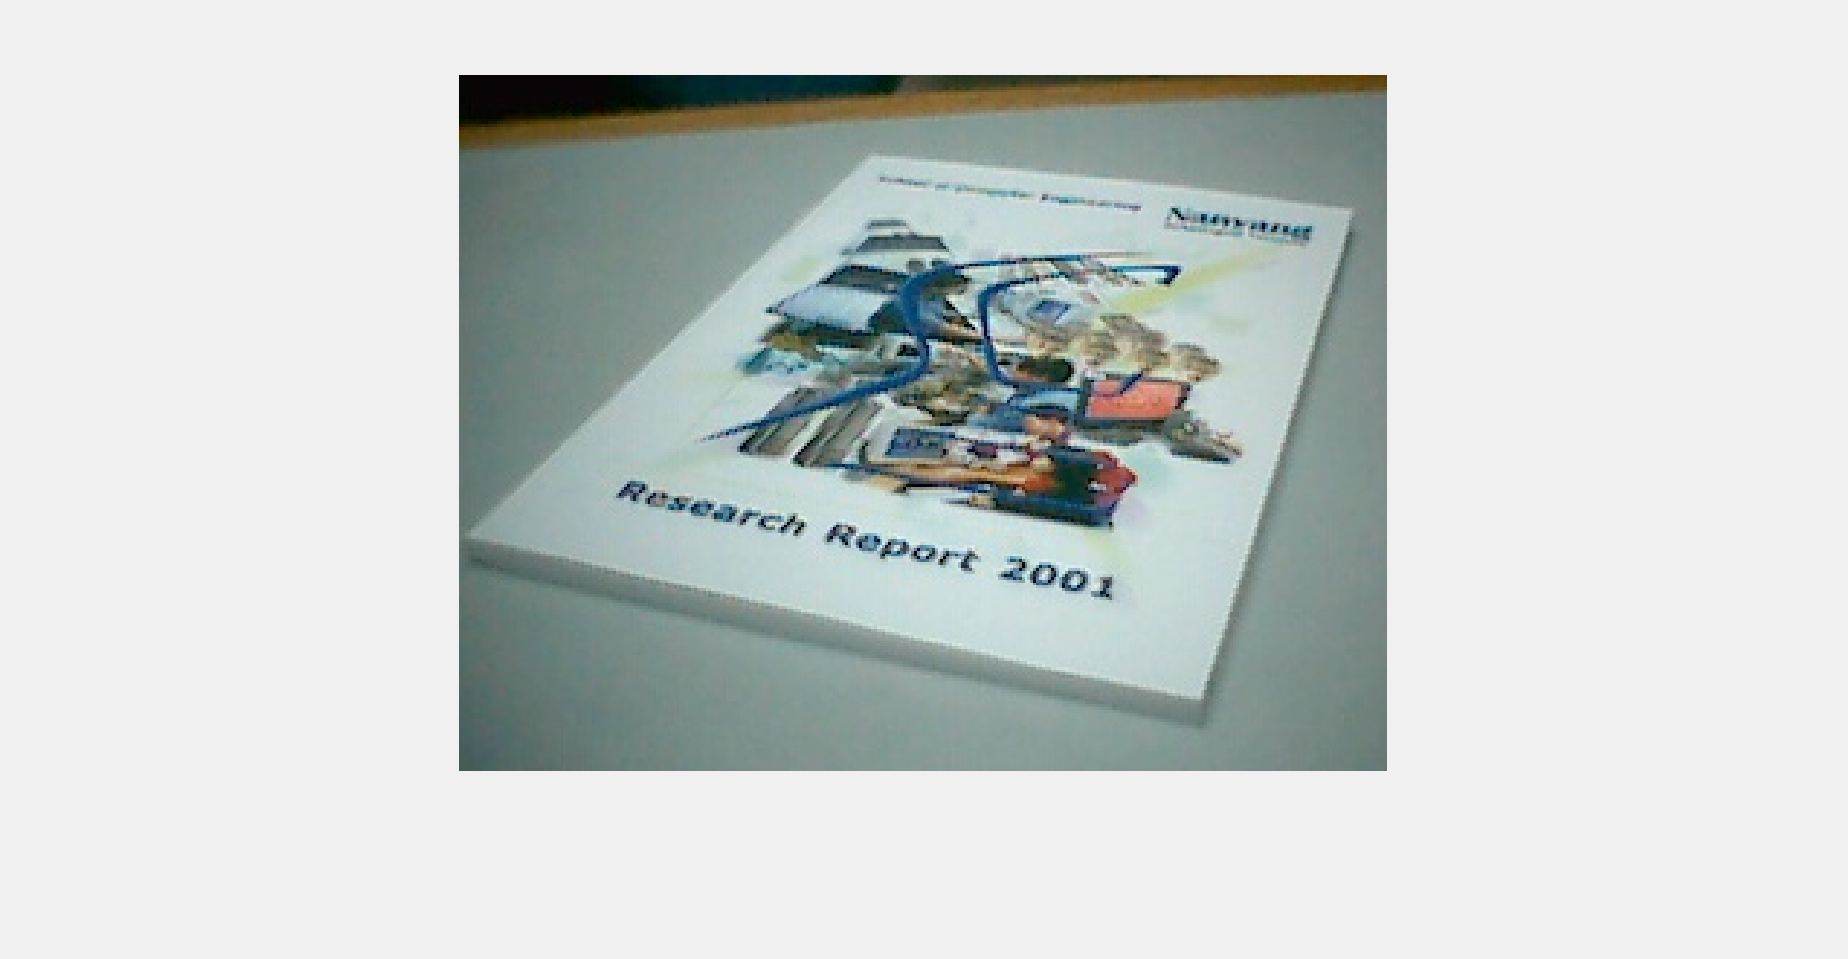

X =   142.7414
  308.2586
    3.0862
  256.8793


Y =    27.5690
   46.5345
  158.9483
  216.5345


% top-left, top-right, bot-left, bot-right
[X, Y] = ginput(4)

Also, specify the vectors x and y to indicate the four corners of your desired image (based on the A4 dimensions), in the same order as above.

x = [15; 215; 15; 215];
y = [10; 10; 307; 307];

c. Set up the matrices required to estimate the projective transformation based on the equation (*) above.

% TODO

The above computes u = $A^{-1}$ v, and you can convert the projective transformation parameters to the normal matrix form by